### Introduction

This scrip is about to research about the meating time of two particular genetic locus. And in this scrip I will use a new kind of random force.

## Data Importing

import parameters

m=1;%just for test
psi=5;%psi=0---> no potential
zeta=100;
H=0.7;
kB=1;
T=1;

import Time interval

delta=0.01;

import Total Time

Tmax=100;
imax=Tmax/delta;

import Total_experiment_number

Total_experiment_number=1000;

## Random Force

We create the random force in this part and smooth it.

The interval of each point is delta

%BH=wfbm(H,imax+1);
%X=1:imax;
%x_length = linspace(1,Tmax);
%BHt=interp1(X,BH(2:imax+1),x_length,'pchip');%smooth the random
%plot(x_length,BHt)%draw the figure to verify

## Initialization

initialization v, x, and a data type

v=zeros(Total_experiment_number,imax+1);
x=zeros(Total_experiment_number,imax+1);
a=zeros(Total_experiment_number,imax+1);
meeting_step=zeros(Total_experiment_number,1);

## Main loop

initialization v, x, and a when t =0

for n=1:Total_experiment_number
    v(n,1)=normrnd(0,(kB*T/m)*0.5);%should be random
    x(n,1)=normrnd(0,(kB*T/(m*psi))*0.5);%should be random
    a(n,1)=0;%no need to be random
    BH=wfbm(H,imax+1);
    for i=1:imax
        KH=i:-1:1;
        x(n,i+1)=x(n,i)+v(n,i)*delta;
        v(n,i+1)=v(n,i)+a(n,i)*delta;
        a(n,i+1)=-(zeta/m)*2*H*(2*H-1)*delta^(2*H-2)*((KH.^(2*H-2))*v(n,1:i)')*delta-psi*x(n,i)+(2*zeta*kB*T)^0.5*(BH(i+1)-BH(i))/delta;%ODE
        if i>=2
            if x(n,i-1)*x(n,i)<=0
                break
            end
        end
    end

monitoring the progress rate

    progress_rate=n/Total_experiment_number*100;
    meeting_step(n,1)=i;%means betwean t=(i-1)*delta adn t=i*delta
    if progress_rate==floor(progress_rate)
        disp(['progress rate  ',num2str(progress_rate),' %'])
    end
end

progress rate  1 %
progress rate  2 %
progress rate  3 %
progress rate  4 %
progress rate  5 %
progress rate  6 %
progress rate  8 %
progress rate  9 %
progress rate  10 %
progress rate  11 %
progress rate  12 %
progress rate  13 %
progress rate  15 %
progress rate  16 %
progress rate  17 %
progress rate  18 %
progress rate  19 %
progress rate  20 %
progress rate  21 %
progress rate  22 %
progress rate  23 %
progress rate  24 %
progress rate  25 %
progress rate  26 %
progress rate  27 %
progress rate  30 %
progress rate  31 %
progress rate  32 %
progress rate  33 %
progress rate  34 %
progress rate  35 %
progress rate  36 %
progress rate  37 %
progress rate  38 %
progress rate  39 %
progress rate  40 %
progress rate  41 %
progress rate  42 %
progress rate  43 %
progress rate  44 %
progress rate  45 %
progress rate  46 %
progress rate  47 %
progress rate  48 %
progress rate  49 %
progress rate  50 %
progress rate  51 %
progress rate  52 %
progress rate  53 %
progress rate  54 %
progress

## Data output

meeting_time_distripution=zeros(floor(max(meeting_step)*delta)+1,1);
for i=1:Total_experiment_number
    meeting_time_distripution(floor(meeting_step(i)*delta)+1,1)=meeting_time_distripution(floor(meeting_step(i)*delta)+1,1)+1;
end

## Plotting and saving

storage_location='C:\Users\zhouquan\OneDrive\research\DNA随机游走模拟\数据模拟\v9';
save([storage_location,'\data\meeting_step_data','.zeta=',num2str(zeta),'.psi=',num2str(psi),'.delta=',num2str(delta),'.H=',num2str(H),'.N=',num2str(Total_experiment_number),'.mat'],"meeting_step");

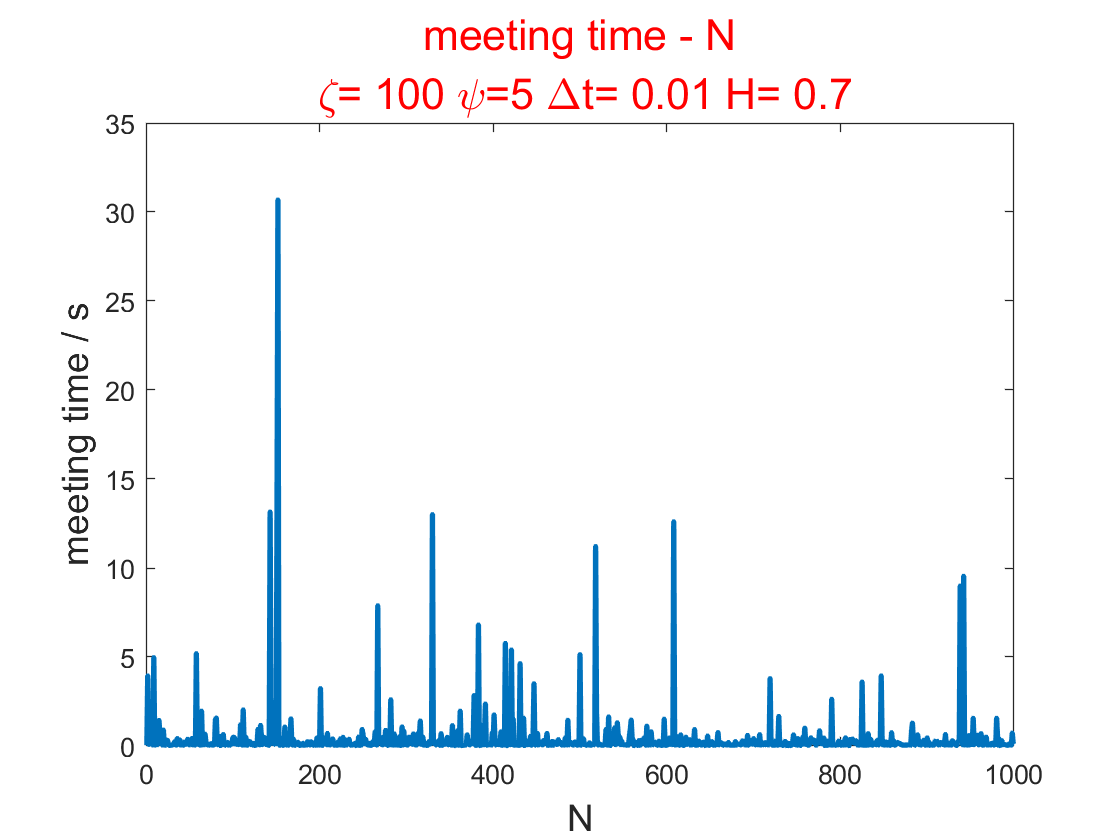

figure
plot(1:Total_experiment_number,meeting_step(:,1)*delta,'LineWidth',2);
xlabel('N','FontSize',14);
ylabel('meeting time / s','FontSize',14);
title({'meeting time - N',[' \zeta= ',num2str(zeta),' \psi=', ...
    num2str(psi),' \Deltat= ',num2str(delta),' H= ',num2str(H)]},'Color','r','FontSize',16);
saveas(gcf,[storage_location,'\image\meeting_time','.zeta=',num2str(zeta),'.psi=',num2str(psi),'.delta=',num2str(delta),'.H=',num2str(H),'.N=',num2str(Total_experiment_number),'.jpg']);

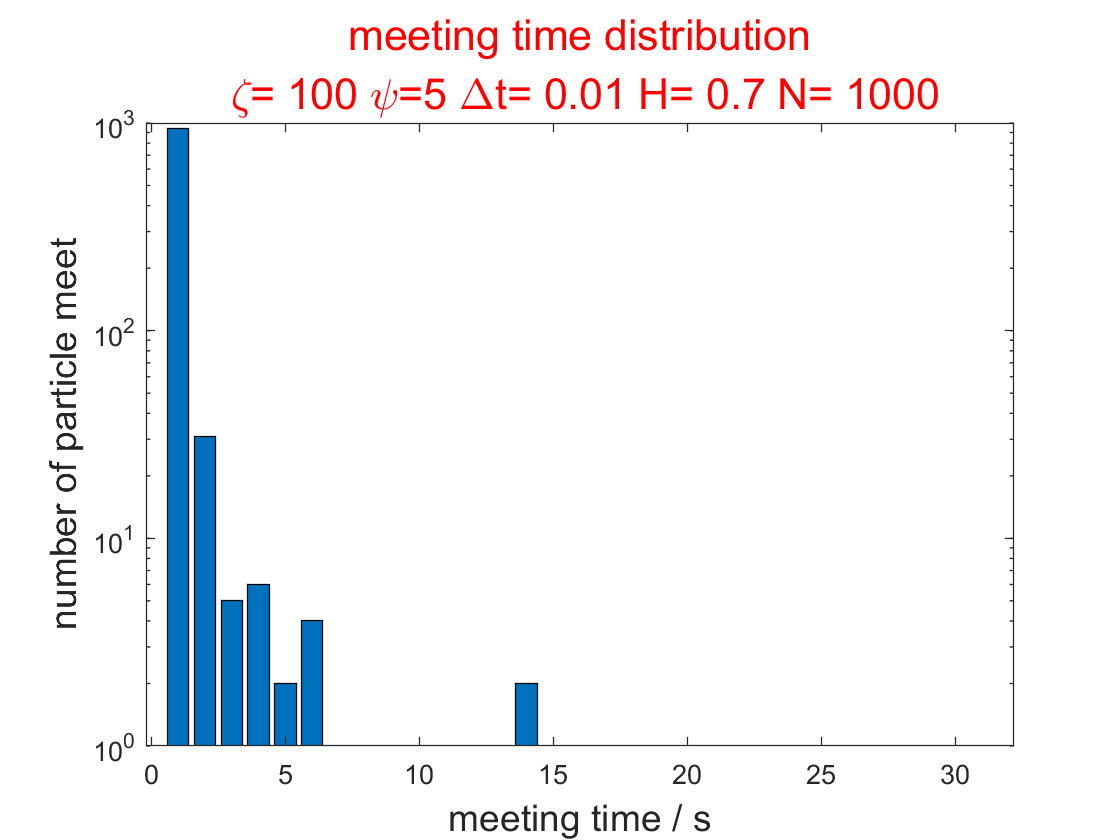

figure
bar(1:floor(max(meeting_step)*delta)+1,meeting_time_distripution(:,1));
set(gca,'yscale','log');
xlabel(['meeting time / s'],'FontSize',14);
ylabel('number of particle meet','FontSize',14);
title({'meeting time distribution',[' \zeta= ',num2str(zeta),' \psi=', ...
    num2str(psi),' \Deltat= ',num2str(delta),' H= ',num2str(H),' N= ',num2str(Total_experiment_number)]},'Color','r','FontSize',16)
saveas(gcf,[storage_location,'\image\meeting_time_distribution','.zeta=',num2str(zeta),'.psi=',num2str(psi),'.delta=',num2str(delta),'.H=',num2str(H),'.N=',num2str(Total_experiment_number),'.jpg']);